datapath = ...
    {"/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Dose_dependent/20221203AchsensorHEK001_dose/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Dose_dependent/20221203AchsensorHEK002_dose/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Dose_dependent/20221203AchsensorHEK003_dose/"...
    }

datapath = 1×3 cell array
    {["/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Dose_dependent/20221203AchsensorHEK001_dose/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Dose_dependent/20221203AchsensorHEK002_dose/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Dose_dependent/20221203AchsensorHEK003_dose/"]}




StateYao_file = ...
    {"analysis_offset0_ROIadjusted_20221208.mat",...
    "analysis_offset0_ROIadjusted_20221205.mat",...
    "analysis_offset0_ROIadjusted_20221206.mat"...
    }

StateYao_file = 1×3 cell array
    {["analysis_offset0_ROIadjusted_20221208.mat"]}    {["analysis_offset0_ROIadjusted_20221205.mat"]}    {["analysis_offset0_ROIadjusted_20221206.mat"]}



summary_files = {};
summary_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Dose_dependent/'

summary_path = '/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/Dose_dependent/'

all_epochs = [2 3 4 5 6 7 8 9 10 11 12 13]; % all the epochs
drug_epochs = [2 3 4 5 6 7 8 9 10 11 12 13];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

CyclePositions = [1]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation
FigureVisible = 'off'

FigureVisible = 'off'

for i =1:3;
    cd(datapath{i});
    load(StateYao_file{i});
    % reference_acqn_num = '010';
    % spc_file = [stateYao.baseName, 'FLIM', reference_acqn_num, '.mat']
    % spc_openCurves(spc_file)
    
    % background_mask = gui.gy.rois{1,1}.mask;
    % reference_image = [stateYao.baseName, reference_acqn_num, '.tif']
    % num_img = stateYao.CyclePositions(end);
    % acq_start = stateYao.CyclePositions(1);
    
    CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions);
    % [intensity_top] = CalcIntensity_topPMT(reference_image, num_img, acq_start, background_mask);
    
    [lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
    % [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all);
    
    [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all, FigureVisible)
    [intensity_response_EC50,lft_response_EC50] = EC50_calc(drug_epochs, epoch_response_intensity_all{1}, epoch_response_lft_all{1})
    
    % [epoch_response_intensity_top_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_top_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_top, lft_all)
    % [intensity_response_top_EC50,lft_response_EC50] = EC50_calc(drug_epochs, epoch_response_intensity_top_all{1}, epoch_response_lft_all{1})
    currTime = datestr(datetime('now'));
    currTime = currTime(1:11);
    save([stateYao.baseName,'_',currTime, '_EC50.mat'],'intensity_response_EC50','lft_response_EC50')
    
    copyfile([stateYao.baseName,'_',currTime, '_EC50.mat'], summary_path)
    copyfile([stateYao.baseName, '_', currTime, '.mat'], summary_path)

    summary_files{i} = [stateYao.baseName,'_',currTime, '_EC50.mat'];


end

epoch_response_intensity_norm_all = 1×1 cell array
    {11×5 double}


epoch_response_lft_norm_all = 1×1 cell array
    {11×5 double}


epoch_response_intensity_all = 1×1 cell array
    {11×5 double}


epoch_response_lft_all = 1×1 cell array
    {11×5 double}


intensity_response_EC50 =          0         0         0         0         0
    0.0092    0.0115   -0.0149   -0.0219   -0.0826
   -0.0027    0.0050    0.0085   -0.0293   -0.1655
    0.1494    0.1569    0.1464    0.1054   -0.1667
    0.1156    0.0807    0.0747    0.0098   -0.2474
    0.4489    0.3834    0.5153    0.4054    0.0783
    0.5188    0.4181    0.6190    0.5426    0.2703
    0.8956    0.6746    0.7892    0.9096    1.0000
    0.9220    0.7472    0.7174    0.8294    0.7260
    1.0000    1.0000    1.0000    1.0000    0.7551


lft_response_EC50 =          0         0         0         0         0
    0.0644   -0.0123    0.0327    0.0235    0.0802
    0.2010    0.0438    0.1719    0.0592    0.0347
    0.3140    0.2353    0.3307    0.2470    0.2844
    0.4524    0.4275    0.4501    0.4293    0.3707
    0.8613    0.7725    0.7576    0.7155    0.6818
    0.8976    0.9032    0.8341    0.8085    0.6911
    1.0000    1.0000    0.9859    1.0000    0.9299
    0.9793    0.9419    0.9579    0.9856    0.9006
    0.9557    0.9596    1.0000    0.9791    1.0000


epoch_response_intensity_norm_all = 1×1 cell array
    {11×4 double}


epoch_response_lft_norm_all = 1×1 cell array
    {11×4 double}


epoch_response_intensity_all = 1×1 cell array
    {11×4 double}


epoch_response_lft_all = 1×1 cell array
    {11×4 double}


intensity_response_EC50 =          0         0         0         0
    0.0536    0.0545    0.0850    0.0137
    0.0573    0.0344    0.0692   -0.0038
    0.1166    0.1044    0.1353    0.0735
    0.0986    0.1176    0.1320    0.0688
    0.2669    0.2932    0.2372    0.2877
    0.3687    0.4064    0.2892    0.3423
    0.6142    0.7469    0.6465    0.6913
    0.6959    0.8913    0.7668    0.7664
    0.9592    0.9915    0.9476    0.9890


lft_response_EC50 =          0         0         0         0
    0.0189   -0.2672   -0.3413   -0.0010
    0.1333   -0.0789   -0.2154    0.1504
    0.1513    0.1248   -0.2674    0.1577
    0.2901    0.0821    0.0075    0.1888
    0.7351    0.5663    0.2237    0.6621
    0.8720    0.7599    0.5943    0.7279
    0.8805    0.8883    0.8499    0.8438
    0.9215    0.9723    0.9373    0.9422
    1.0000    0.9554    1.0000    1.0000


epoch_response_intensity_norm_all = 1×1 cell array
    {11×4 double}


epoch_response_lft_norm_all = 1×1 cell array
    {11×4 double}


epoch_response_intensity_all = 1×1 cell array
    {11×4 double}


epoch_response_lft_all = 1×1 cell array
    {11×4 double}


intensity_response_EC50 =          0         0         0         0
   -0.0306   -0.0276   -0.0225   -0.0927
   -0.0956   -0.1555   -0.0136   -0.0820
   -0.0390   -0.0888    0.1337    0.0686
   -0.1103   -0.0778    0.0639   -0.0387
    0.0761    0.1953    0.3350    0.2206
    0.2969    0.3976    0.4226    0.3426
    0.7670    0.8175    0.8175    0.6802
    0.7923    0.8561    0.8901    0.8344
    1.0000    1.0000    1.0000    1.0000


lft_response_EC50 =          0         0         0         0
    0.1302    0.0981   -0.1092   -0.1018
    0.1849    0.1647   -0.0144   -0.0827
    0.3042    0.1761    0.0452    0.1037
    0.3843    0.3026    0.2508    0.2934
    0.6278    0.6340    0.5697    0.4912
    0.7928    0.7222    0.7085    0.7349
    0.8726    0.9081    0.9255    0.9135
    0.9483    0.8726    0.8840    0.9616
    0.9278    0.9458    0.9949    0.8414



cd(summary_path)
save('summary_files.mat', 'summary_files')


cd(summary_path)
load('summary_files.mat')

lft_response_all = [];
intensity_response_all = [];

for i = 1:3
    load(summary_files{i})
    lft_response_all = [lft_response_all lft_response_EC50 NaN(11,1)];
    intensity_response_all = [intensity_response_all intensity_response_EC50 NaN(11,1)];
end

save('summary_data.mat', 'lft_response_all', 'intensity_response_all')

i =2;
cd(datapath{i});
load(StateYao_file{i});
% reference_acqn_num = '010';
% spc_file = [stateYao.baseName, 'FLIM', reference_acqn_num, '.mat']
% spc_openCurves(spc_file)

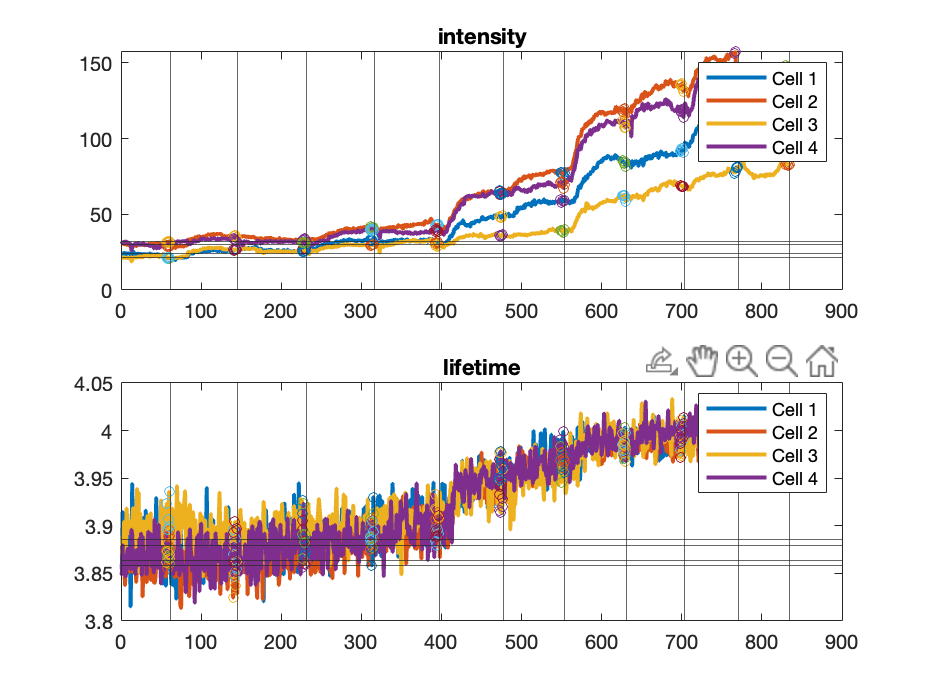

epoch_response_intensity_norm_all = 1×1 cell array
    {11×4 double}


epoch_response_lft_norm_all = 1×1 cell array
    {11×4 double}


epoch_response_intensity_all = 1×1 cell array
    {11×4 double}


epoch_response_lft_all = 1×1 cell array
    {11×4 double}



% background_mask = gui.gy.rois{1,1}.mask;
% reference_image = [stateYao.baseName, reference_acqn_num, '.tif']
% num_img = stateYao.CyclePositions(end);
% acq_start = stateYao.CyclePositions(1);

CalculateROIBasedOnTopPixels(5, 0.66);
% [intensity_top] = CalcIntensity_topPMT(reference_image, num_img, acq_start, background_mask);

[lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels();
% [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all);

[epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)

[intensity_response_EC50,lft_response_EC50] = EC50_calc(drug_epochs, epoch_response_intensity_all{1}, epoch_response_lft_all{1})

intensity_response_EC50 =          0         0         0         0
    0.0536    0.0545    0.0850    0.0137
    0.0573    0.0344    0.0692   -0.0038
    0.1166    0.1044    0.1353    0.0735
    0.0986    0.1176    0.1320    0.0688
    0.2669    0.2932    0.2372    0.2877
    0.3687    0.4064    0.2892    0.3423
    0.6142    0.7469    0.6465    0.6913
    0.6959    0.8913    0.7668    0.7664
    0.9592    0.9915    0.9476    0.9890


lft_response_EC50 =          0         0         0         0
    0.0189   -0.2672   -0.3413   -0.0010
    0.1333   -0.0789   -0.2154    0.1504
    0.1513    0.1248   -0.2674    0.1577
    0.2901    0.0821    0.0075    0.1888
    0.7351    0.5663    0.2237    0.6621
    0.8720    0.7599    0.5943    0.7279
    0.8805    0.8883    0.8499    0.8438
    0.9215    0.9723    0.9373    0.9422
    1.0000    0.9554    1.0000    1.0000



% [epoch_response_intensity_top_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_top_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_top, lft_all)
% [intensity_response_top_EC50,lft_response_EC50] = EC50_calc(drug_epochs, epoch_response_intensity_top_all{1}, epoch_response_lft_all{1})

save([stateYao.baseName, '_EC50.mat'],'intensity_response_EC50','lft_response_EC50')


i =3;
cd(datapath{i});
load(StateYao_file{i});
% reference_acqn_num = '010';
% spc_file = [stateYao.baseName, 'FLIM', reference_acqn_num, '.mat']
% spc_openCurves(spc_file)

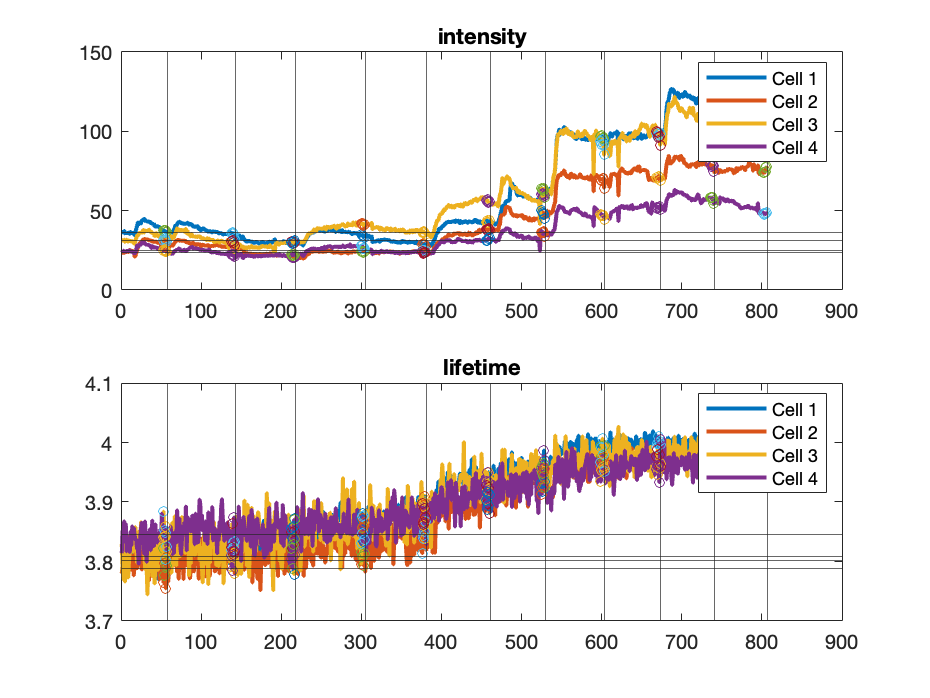

epoch_response_intensity_norm_all = 1×1 cell array
    {11×4 double}


epoch_response_lft_norm_all = 1×1 cell array
    {11×4 double}


epoch_response_intensity_all = 1×1 cell array
    {11×4 double}


epoch_response_lft_all = 1×1 cell array
    {11×4 double}



% background_mask = gui.gy.rois{1,1}.mask;
% reference_image = [stateYao.baseName, reference_acqn_num, '.tif']
% num_img = stateYao.CyclePositions(end);
% acq_start = stateYao.CyclePositions(1);

CalculateROIBasedOnTopPixels(5, 0.66);
% [intensity_top, background] = CalcIntensity_topPMT(reference_image, num_img, acq_start, background_mask);

[lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels();

[epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)

[intensity_response_EC50,lft_response_EC50] = EC50_calc(drug_epochs, epoch_response_intensity_all{1}, epoch_response_lft_all{1})

intensity_response_EC50 =          0         0         0         0
   -0.0306   -0.0276   -0.0225   -0.0927
   -0.0956   -0.1555   -0.0136   -0.0820
   -0.0390   -0.0888    0.1337    0.0686
   -0.1103   -0.0778    0.0639   -0.0387
    0.0761    0.1953    0.3350    0.2206
    0.2969    0.3976    0.4226    0.3426
    0.7670    0.8175    0.8175    0.6802
    0.7923    0.8561    0.8901    0.8344
    1.0000    1.0000    1.0000    1.0000


lft_response_EC50 =          0         0         0         0
    0.1302    0.0981   -0.1092   -0.1018
    0.1849    0.1647   -0.0144   -0.0827
    0.3042    0.1761    0.0452    0.1037
    0.3843    0.3026    0.2508    0.2934
    0.6278    0.6340    0.5697    0.4912
    0.7928    0.7222    0.7085    0.7349
    0.8726    0.9081    0.9255    0.9135
    0.9483    0.8726    0.8840    0.9616
    0.9278    0.9458    0.9949    0.8414



% [epoch_response_intensity_top_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_top_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_top, lft_all)
% [intensity_response_top_EC50,lft_response_EC50] = EC50_calc(drug_epochs, epoch_response_intensity_top_all{1}, epoch_response_lft_all{1})


